## COVID-19 in BC

**Objective: **To fit the two-age group *SI(R)I(UR)R *model of COVID-19 transmission to the reported case data under various constraints.

## Initialization 

clear all; clc;

%% Select region, timeframe, age-cutoff
region = 'BC';
start_date = 'Aug 01, 2020';
end_date = 'Oct 31, 2020';
age_cutoff = 60;
Month = 'Sept';

%% Set parameters
D_T = 5.0;
D = [D_T, D_T]; % Mean infectious period for an I in Group i
T_T = 0.25;
T = [T_T,T_T]; % Ascertainment fraction of I in Group i 
N = pop_two_groups(age_cutoff); % Estimate for population of Group i 
tspan = 1:1:(datenum(end_date)-datenum(start_date)+1); % timespan over which ODE solved

%% Import data and format to yield cumulative reported cases and initial active cases
dataI = readtable('pathway.csv'); % replace with pathway of file storing cumulative reported case data
observedI = data_selection_two_groups(dataI, start_date, end_date);
% y1 = init_cond_two_groups(dataI, start_date, D_T, N, T);

## Plotting Optima and Error

optima_short = @(T_test) optima_fun(T_test, D, N, tspan, Month, dataI, start_date, observedI);
error_short = @(T_test) error_fun(T_test, D, N, tspan, Month, dataI, start_date, observedI);


AF = 1:0.1:100;
num_AF = length(AF);

optima = zeros(1,num_AF);

% for i=1:num_AF
%     optima(i) = optima_short(AF(i)/100);
% end
% 
% optima
% 
% plot(AF, optima)
% ylim([0.047, 0.055])
% grid on;
% grid minor;
% set(gca, 'FontSize', 22)
% set(gca, 'FontName', 'Arial')
% ylabel('p_{opt}')
% xtickformat('percentage')
% xlabel('Ascertainment Fraction')

error_vector = zeros(1,num_AF);

for i=1:num_AF
    error_vector(i) = error_short(AF(i)/100);
end


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 


error_vector

error_vector =     0.2150    0.1822    0.1632    0.1531    0.1487    0.1482    0.1501    0.1537    0.1584    0.1637    0.1695    0.1754    0.1814    0.1874    0.1934    0.1992    0.2048    0.2104    0.2157    0.2208    0.2258    0.2306    0.2352    0.2397    0.2440    0.2481    0.2521    0.2559    0.2596    0.2632    0.2666    0.2699    0.2731    0.2761    0.2791    0.2819    0.2847    0.2874    0.2900    0.2925    0.2949    0.2972    0.2995    0.3017    0.3038    0.3059    0.3079    0.3098    0.3117    0.3135


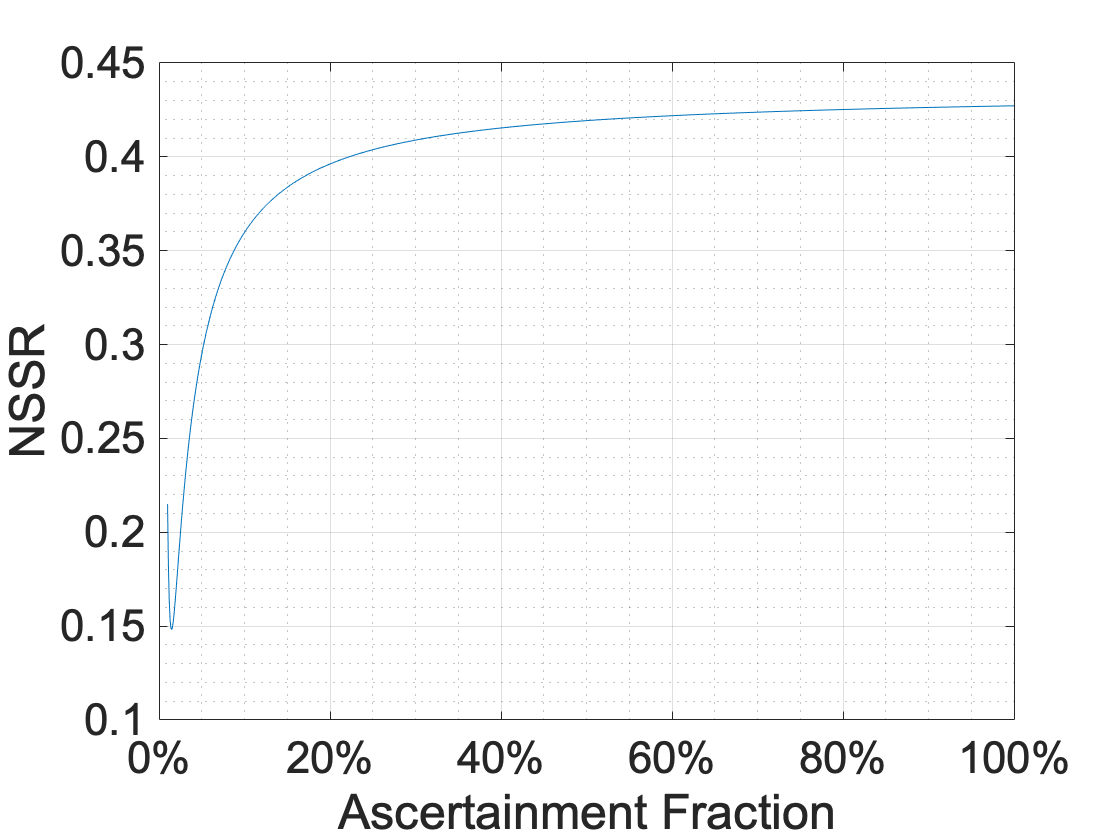

Unrecognized function or variable 'para_opt'.


plot(AF, error_vector)
% ylim([0.047, 0.055])
grid on;
grid minor;
set(gca, 'FontSize', 22)
set(gca, 'FontName', 'Arial')
ylabel('NSSR')
xtickformat('percentage')
xlabel('Ascertainment Fraction')